# **Standing wave dispersion simulation **

clear
clc

`현재 위치 설정 및 경로추가

cd 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 3.0 20250703'
addpath 'C:\Users\PC\OneDrive\UNIST\simulation\Standing wave dispersion\STN wave dispersion 3.0 20250703\data'

랜덤 방식 설정

rng('shuffle'); % Seed the random number generator based on the current time

vx_tilt_list = [8]

vx_tilt_list = 8

for vx_tilt_ind = 1:numel(vx_tilt_list)

기본 상수 설정

load("STN_constants_fullpaper.mat"); %load default constants
%you can re-define contants here!
vx_caused_tilted=vx_tilt_list(vx_tilt_ind)
MAX =2000000
% Ij_distribution=0
% Ips_y =0
% Ips_z =0

vx_caused_tilted = 9

MAX = 2000000

세기(I) 리스트 작성

%I1, I2 setting (I1과 I2의 행렬 크기를 같게 하세요.)

% SW
% I1_list = [0:0.05:8];
% I2_list = [0:0.05:8];
I1_list = [0 0.6 0.8 1 1.2 1.4 1.6 1.8 2 2.2 2.4 2.6 2.8 3 3.5 4 4.5 5]*0.675;
I2_list = [0 0.6 0.8 1 1.2 1.4 1.6 1.8 2 2.2 2.4 2.6 2.8 3 3.5 4 4.5 5]*0.675;

%PSW 
% I1_list = [0:0.5:82];
% I2_list = ones(1,numel(I1_list))*0.2;

% I1_list = [0 1.8 3.2 5.0 7.2 9.8 12.8 14.4 16.2 20.0 24.2 28.8 33.8 39.2 45 61.3 80.1]*0.675
% I2_list = [0, ones(1,numel(I1_list)-1)*0.2*0.675]
% syms x
% a_list=[22.2:0.2:30]
% b = 1.6*1.6 
% 
% alpha = zeros(numel(a_list),1);
% beta = zeros(numel(a_list),1);
% for idx = 1:numel(a_list)
%     a=a_list(idx);
%     f = x^2 -a*x +b;
%     sol=double(solve(f));
%     alpha(idx) = sol(1);
%     beta(idx) = sol(2);
% end
% 
% I1_list = alpha'*0.7
% I2_list = beta'*0.7

% off 
% I1_list = [0];
% I2_list = [0];
Cell_velocity=cell(numel(I2_list),1);

I1_list =          0    1.2150    2.1600    3.3750    4.8600    6.6150    8.6400    9.7200   10.9350   13.5000   16.3350   19.4400   22.8150   26.4600   30.3750   41.3775   54.0675


I2_list =          0    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350    0.1350


Trajectory calculation.

for I_ind = 1:numel(I2_list)
run('Main_code.m') %Main code returns the velocity of x,y,z
% run('Main_code_CUDA.m') %Main code returns the velocity of x,y,z
Cell_velocity{I_ind}=velocity;% Cell_velocity(intensity list) = velocity of particle, 
end

Elapsed time is 985.988260 seconds.
Elapsed time is 1184.019419 seconds.
Elapsed time is 1190.427803 seconds.
Elapsed time is 1201.647293 seconds.
Elapsed time is 1191.430760 seconds.
Elapsed time is 1216.545501 seconds.
Elapsed time is 1192.654690 seconds.
Elapsed time is 1210.197357 seconds.
Elapsed time is 1210.291464 seconds.
Elapsed time is 1186.566795 seconds.
Elapsed time is 1209.781908 seconds.
Elapsed time is 1190.579812 seconds.
Elapsed time is 1197.858617 seconds.
Elapsed time is 1200.947686 seconds.
Elapsed time is 1207.263059 seconds.
Elapsed time is 1216.319627 seconds.
Elapsed time is 1244.566111 seconds.


Image blurring 상수 설정

vel_pix=2.28; %픽셀당 속도
rep_std=4.0; %electron repulsion standard deviation
rep_vel=2.7; %electron repulsion speed standard deviation
atten_factorx =1/0.9278;
atten_factory =1/0.9453;

Image blurring (z축 방향으로는 계산안함)

run('Image_code_voigt.m')

plotting

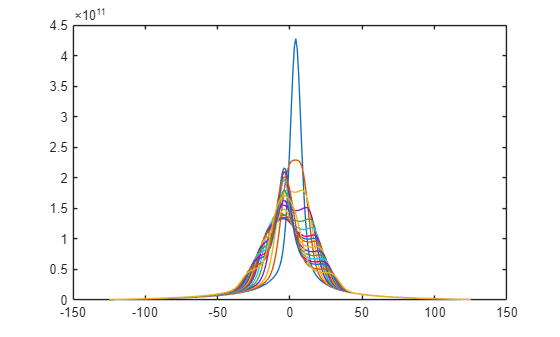

plot(xgrid,sumx)

Save

%making the data saved
constants = struct();
constants.I1_list = I1_list;
constants.I2_list = I2_list;
constants.lambda = lambda;
constants.MAX = MAX;
constants.tend = tend;
constants.tstep = tstep;
constants.vx_caused_tilted = vx_caused_tilted;
constants.vel_pix=vel_pix;
constants.Dye_sigma=Dye_sigma;
constants.w0z = w0z;
constants.w0y = w0y;
constants.jm_data  = jm_data;
% constants.x_init_distribution = x_init_distribution;
constants.x_init_vel_sigma= x_init_vel_sigma;
constants.y_init_vel_sigma= y_init_vel_sigma; 
constants.z_init_vel_sigma = z_init_vel_sigma;
constants.z_init_vel_off = z_init_vel_off;
constants.Dye_tau=Dye_tau;
constants.Ips_z = Ips_z;
constants.Ips_y = Ips_y;
constants.Ij_distribution = Ij_distribution;
constants.tau = tau;

data = struct();
data.xgrid=xgrid';
data.ygrid=ygrid';
data.img_matrix=img_matrix;
data.sumx=sumx;
data.sumy=sumy;

filename=sprintf("data_SW_%2.0f_20260323_9m_s.mat",vx_tilt_ind)

save(filename,'data','I1_list','I2_list','Cell_velocity','constants');

filename = "data_PSW_ 1_20260320_9m_s.mat"

end